# Transfer Learning with Pretrained Audio Networks in Deep Network Designer

This example shows how to interactively fine-tune a pretrained network to classify new audio signals using Deep Network Designer.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network with randomly initialized weights from scratch. You can quickly transfer learned features to a new task using a smaller number of training signals.

This example retrains YAMNet, a pretrained convolutional neural network, to classify a new set of audio signals.

## Add Path

addpath("AirCompressorDataset")
addpath("yamnet")

## Load Data

Create an `audioDatastore` object to manage the data. 

Split the data into training, validation, and test sets using the `splitEachLabel` function.

Use the `transform` function to preprocess the data using the function `audioPreprocess`, found at the end of this example. For each signal: 

- Use [`yamnetPreprocess`](docid:audio_ref#mw_bc2966eb-df69-4f8f-b8fc-33b8a4c2b63e) to generate mel spectrograms suitable for training using YAMNet. Each audio signal produces multiple spectrograms.

- Duplicate the class label for each of the spectrograms.

tdsTrain = transform(adsTrain,@audioPreprocess,IncludeInfo=true);
tdsValidation = transform(adsValidation,@audioPreprocess,IncludeInfo=true);
tdsTest = transform(adsTest,@audioPreprocess,IncludeInfo=true);

## Select Pretrained Network

Prepare and train the network interactively using [**Deep Network Designer**](docid:nnet_ref#mw_301a3a9d-998a-4668-aec4-f94646b76921). To open Deep Network Designer, on the **Apps** tab, under **Machine Learning and Deep Learning**, click the app icon. Alternatively, you can open the app from the command line.

deepNetworkDesigner

## Prepare Network for Transfer Learning

To prepare the network for transfer learning, in the **Designer** pane, replace the last learnable layer and the final classification layer.

**Replace Last Learnable Layer**

Drag a new `fullyConnectedLayer` onto the canvas. The `OutputSize` property defines the number of classes for classification problems. Change `OutputSize` to the number of classes in the new data, in this example, 8.

Change the learning rates so that learning is faster in the new layer than in the transferred layers by setting `WeightLearnRateFactor` and `BiasLearnRateFactor` to `10`.

Delete the last fully connected layer and connect your new layer instead.

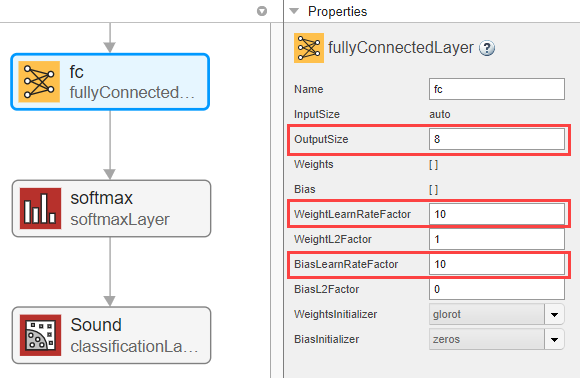

## Import Data

To load the data into Deep Network Designer, on the **Data** tab, click **Import Data** > **Import Datastore**. Select `tdsTrain` as the training data and `tdsValidation` as the validation data.

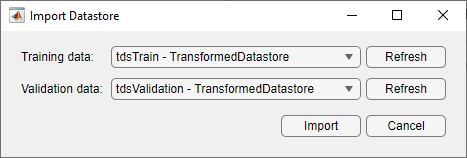

## Test Network

Classify the test data using the exported network and the `classify` function.

%create the test ground truth


%use classify function to classify the data


%see the accuracy of the model


## Supporting Function - Generate Spectrograms 

The function `audioPreprocess` uses [`yamnetPreprocess`](docid:audio_ref#mw_bc2966eb-df69-4f8f-b8fc-33b8a4c2b63e) to generate mel spectrograms from `audioIn` that you can feed to the YAMNet pretrained network. Each input signal generates multiple spectrograms, so the labels must be duplicated to create a one-to-one correspondence with the spectrograms.

function [data,info] = audioPreprocess(audioIn,info)
class = info.Label;
fs = info.SampleRate;
features = yamnetPreprocess(audioIn,fs);

numSpectrograms = size(features,4);

Unrecognized function or variable 'trainedNetwork_1'.


data = cell(numSpectrograms,2);
for index = 1:numSpectrograms
    data{index,1} = features(:,:,:,index);
    data{index,2} = class;
end
end

## References

[1] Verma, Nishchal K., Rahul Kumar Sevakula, Sonal Dixit, and Al Salour. “Intelligent Condition Based Monitoring Using Acoustic Signals for Air Compressors.” IEEE Transactions on Reliability 65, no. 1 (March 2016): 291–309. https://doi.org/10.1109/TR.2015.2459684.

*Copyright 2021 The MathWorks, Inc.*